# Miniprojekt 4 - Nøjagtig frekvensmåling

## Indledning

## Formål

## Analyse

!!opstil Krav!!

gFs = 50.1111   % Grundfrekvens for begge signaler

gFs = 50.1111

## Opgaven

### Tids- og frekvensanalyse

clear;
load('signal_IEC60255_50_1111Hz.mat')
fs = signal.fs; % Samplingfrekvens på 10 kHz
x1 = signal.x1; % Det rene sinus signal
x2 = signal.x2; % Signal med 40 harmoniske overtoner
N = length(x1); % Antal samples


Først vil de to signaler blive plottet med en tidsakse i intervallet fra 0 til 55 ms.

Periode tiden findes.

ts = 1/fs % Sample tid

ts = 1.0000e-04

Nu bestemmes tiden for plottet.

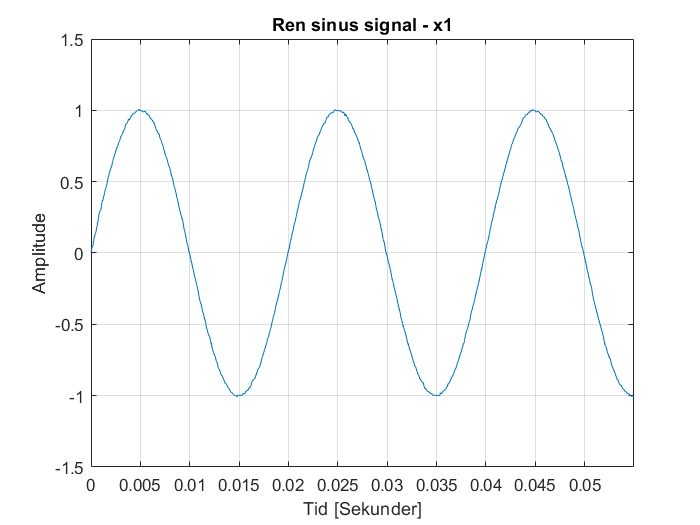

t = 0:ts:(N*ts)-ts; % Varighed
plot(t,x1)
xlim([0 0.055])
title('Ren sinus signal - x1')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')

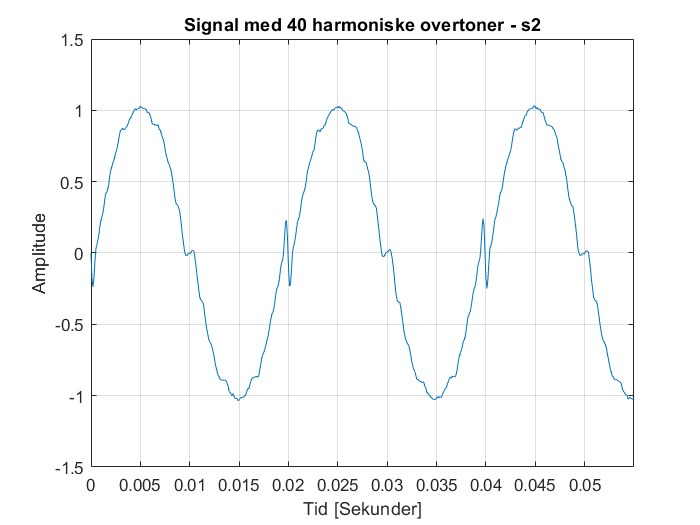

plot(t,x2)
title('Signal med 40 harmoniske overtoner - s2')
grid on
xlim([0 0.055])
xlabel('Tid [Sekunder]')
ylabel('Amplitude')

Nu beregnes DFT for signalerne, samt plot af amplityde spektrene. Men først vil vi bestemme de nødvendige antal samples, for at opnå en afvielse på maksimalt +- 10mHz. 

delta_f = 0.02;  % Frekvens opløsningen
Nny = fs/delta_f % Minimum antal samples 

Nny = 500000


% Der er noget med vores frekvensopløsningen som ikke passer, jeg har
% snakket med kristian og kan siger at der vores frekvens opløsning er 0.01
% og ikke 0.02 hvilket giver 1.000.000 og så passer kravet ikke med de
% 50.1111 og så sagde han at det skulle være på en anden måde hvilket jeg
% ikke forstod!!!

Da FFT'en tager sampels med $2^n$, så findes den exponent der er efter 500.000 

Nny = 2^nextpow2(Nny) % Minimum antal samples i n'te potent

Nny = 524288

DFTx1 = fft(x1,Nny); % DFT for x1
DFTx2 = fft(x2,Nny); % DFT for x2
k = 0:Nny-1;    % Frekvens pins
f = k*fs/Nny;   % Frekvensakse

Nu plottes amplitudespektret for både det rene signal og signalet med 40 harmoniske overtoner op til nyquist.

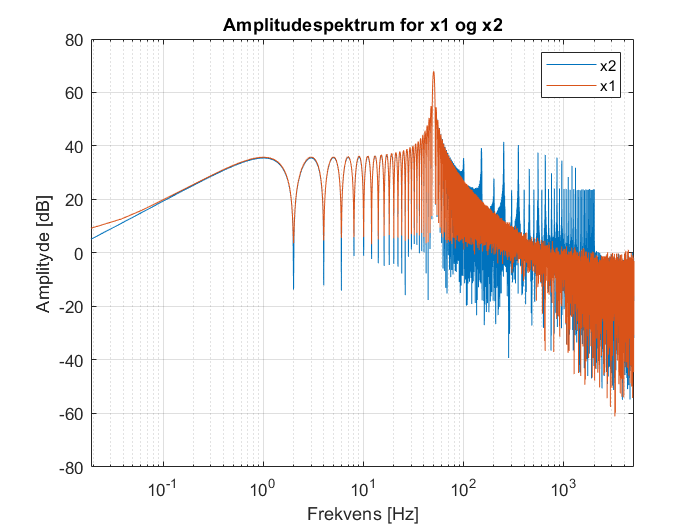

semilogx(f(floor(1:end/2)),20*log10(abs(DFTx2(floor(1:end/2)))))
hold on
semilogx(f(floor(1:end/2)),20*log10(abs(DFTx1(floor(1:end/2)))))
hold off
grid on
title('Amplitudespektrum for x1 og x2')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x2","x1")
xlim([0,fs/2]); % x-akse skalering

Vi vil nu finde den dominerede frekvens og herudfra se om vi opfylder kravet om frekvensopløsningen

[max_amplitudex2, max_frekvens_binx2] = max(DFTx2(floor(1:end/2)))

max_amplitudex2 = 1.9808e+01 - 2.4952e+03i

max_frekvens_binx2 = 2628

max_frekvensx2 = f(max_frekvens_binx2)

max_frekvensx2 = 50.1060

For at finde de harmoniske frekvenskomponenter i signalet x2, plottes amplitudespektret med lineær frekvensakse, for at kunne tælle overtonerne.

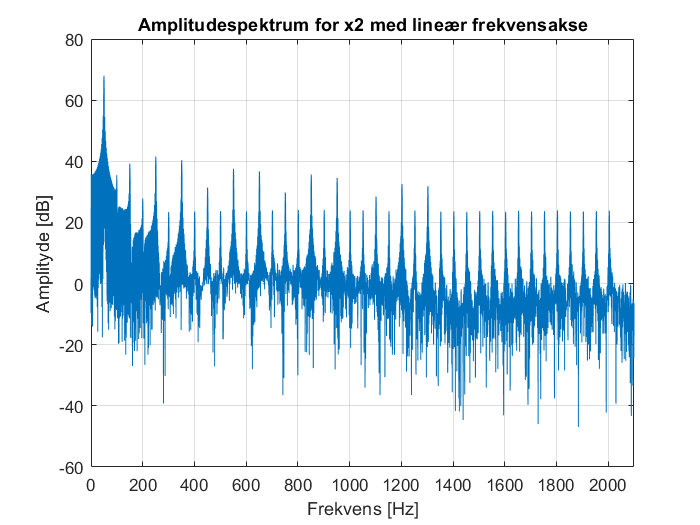

plot(f(floor(1:end/2)),20*log10(abs(DFTx2(floor(1:end/2)))))
grid on
title('Amplitudespektrum for x2 med lineær frekvensakse')
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
xlim([0,2100]); % x-akse skalering

Ud fra plottet ovenfor kan det tælles at der er 40 overtoner. Vi har herved fundet de harmoniske frekvenskomponenter af signalet.

### Hurtig frekvensestimering med zero crossing

#### Filtrering

Nu designes tre forskellige 2. ordens lavpas IIR filtre for at filtre de ikke ønskede højere harmoniske frekvenser fra. Alle filtrene skal have en cut-off til noget højere end den dominerende frekvens.

fc = 50.1111 % Cutoff frekvens ud fra grundfrekvensen

fc = 50.1111

Der startes med Butterworth filtret. 

[butterB,butterA] = butter(2,2*fc/fs,"low");
%fvtool(butterB,butterA);

Chebyshev type 1 filteret designes.

[chebyB,chebyA] = cheby1(2,12,2*fc/fs,"low");
%fvtool(chebyB,chebyA);

Chebyshev type 2 filteret designes.

[cheby2B,cheby2A] = cheby2(2,20,2*fc/fs,"low");
%fvtool(cheby2B,cheby2A);

Et eliptisk filtre laves.

[ellipB,ellipA] = ellip(2,1,50,2*fc/fs,"low"); %%hvad skal ripple sættes til%%
%fvtool(ellipB,ellipA);

Nu påtrykkes signalerne de forskellige filtre.

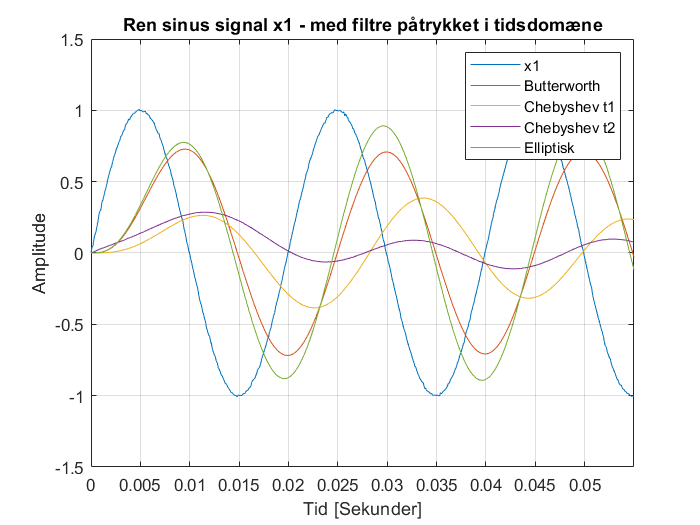

x1butter = filter(butterB,butterA,x1);
x1cheby = filter(chebyB,chebyA,x1);
x1cheby2 = filter(cheby2B,cheby2A,x1);
x1ellip = filter(ellipB,ellipA,x1);


plot(t,x1,t,x1butter,t,x1cheby,t,x1cheby2,t,x1ellip)
xlim([0 0.055])
title('Ren sinus signal x1 - med filtre påtrykket i tidsdomæne')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')
legend("x1","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk")

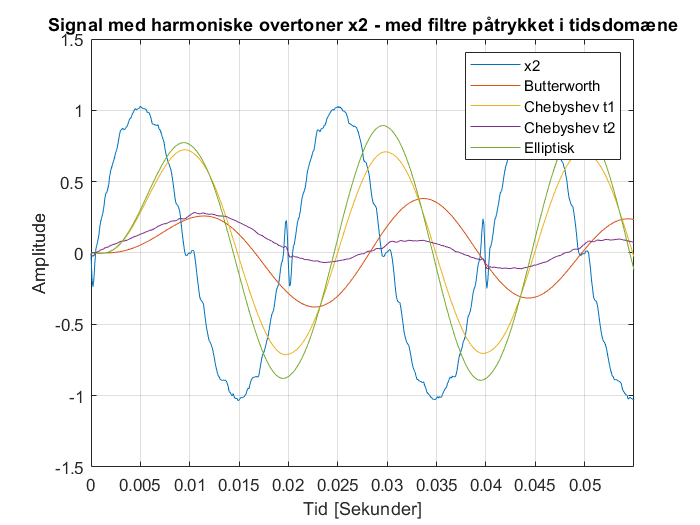

x2butter = filter(butterB,butterA,x2);
x2cheby = filter(chebyB,chebyA,x2);
x2cheby2 = filter(cheby2B,cheby2A,x2);
x2ellip = filter(ellipB,ellipA,x2);


plot(t,x2,t,x2cheby,t,x2butter,t,x2cheby2,t,x2ellip)
xlim([0 0.055])
title('Signal med harmoniske overtoner x2 - med filtre påtrykket i tidsdomæne')
grid on
xlabel('Tid [Sekunder]')
ylabel('Amplitude')
legend("x2","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk")

Amplitudespektret findes ved brug af DFT. Først for x1.

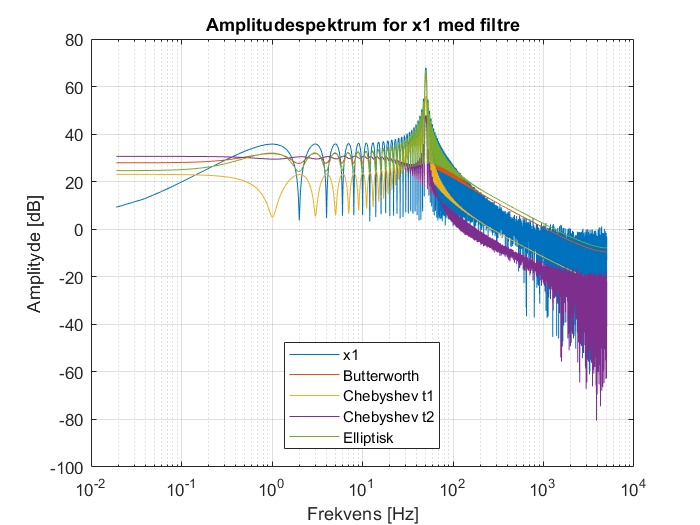

DFTx1butter = fft(x1butter,Nny);
DFTx1cheby = fft(x1cheby,Nny);
DFTx1cheby2 = fft(x1cheby2,Nny);
DFTx1ellip = fft(x1ellip,Nny);

semilogx(f(floor(1:end/2)),real(20*log10(DFTx1(floor(1:end/2)))))
hold on
semilogx(f(floor(1:end/2)),real(20*log10(DFTx1butter(floor(1:end/2)))))
semilogx(f(floor(1:end/2)),real(20*log10(DFTx1cheby(floor(1:end/2)))))
semilogx(f(floor(1:end/2)),real(20*log10(DFTx1cheby2(floor(1:end/2)))))
semilogx(f(floor(1:end/2)),real(20*log10(DFTx1ellip(floor(1:end/2)))))
hold off

grid on
title('Amplitudespektrum for x1 med filtre')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x1","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk","Location","best")

Nu for x2.

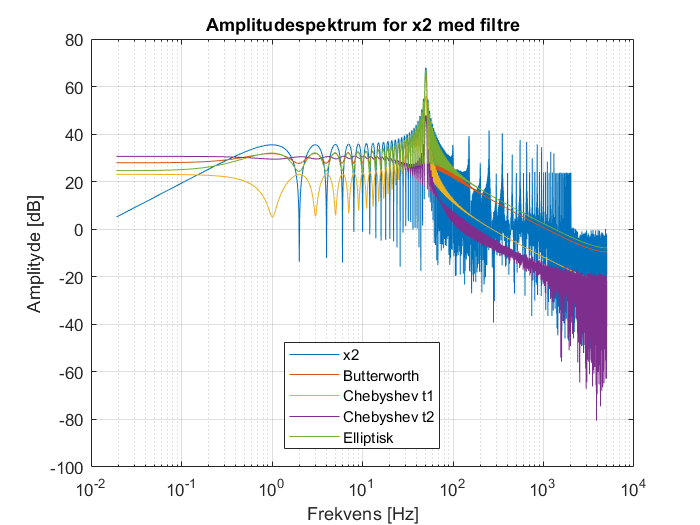

DFTx2butter = fft(x1butter,Nny);
DFTx2cheby = fft(x1cheby,Nny);
DFTx2cheby2 = fft(x1cheby2,Nny);
DFTx2ellip = fft(x1ellip,Nny);

semilogx(f(floor(1:end/2)),real(20*log10(DFTx2(floor(1:end/2)))))
hold on
semilogx(f(floor(1:end/2)),real(20*log10(DFTx2butter(floor(1:end/2)))))
semilogx(f(floor(1:end/2)),real(20*log10(DFTx2cheby(floor(1:end/2)))))
semilogx(f(floor(1:end/2)),real(20*log10(DFTx2cheby2(floor(1:end/2)))))
semilogx(f(floor(1:end/2)),real(20*log10(DFTx2ellip(floor(1:end/2)))))
hold off

grid on
title('Amplitudespektrum for x2 med filtre')           
xlabel('Frekvens [Hz]')
ylabel('Amplityde [dB]')
legend("x2","Butterworth","Chebyshev t1", "Chebyshev t2", "Elliptisk","Location","best")

#### Zero crossing algoritme